## **Pnömoni Tespiti — CNN ile Görüntü Sınıflandırma**

### **1. Veri Hazırlığı**

### **1.1 Ortam Hazırlığı ve Dataset Kontrolü**

Bu bölümde çalışma ortamını hazırlayıp dataset klasörünün doğru konumda olduğunu kontrol ediyoruz. Dataset, NORMAL ve PNEUMONIA olmak üzere iki sınıfa ayrılmış chest X-ray görüntülerinden oluşmaktadır.

% Workspace temizleme
clear; clc; close all;

% Dataset yolunu tanımla (göreceli yol — repo içinde)
datasetPath = fullfile(pwd, 'data', 'chest_xray');

% Klasörün var olup olmadığını kontrol et
if exist(datasetPath, 'dir')
    fprintf('Dataset klasörü bulundu: %s\n', datasetPath);
    
    % Alt klasörleri listele
    subFolders = dir(datasetPath);
    subFolders = subFolders([subFolders.isdir] & ~ismember({subFolders.name}, {'.', '..'}));
    
    fprintf('\nAlt klasörler:\n');
    for i = 1:length(subFolders)
        fprintf('  - %s\n', subFolders(i).name);
    end
else
    error('Dataset klasörü bulunamadı! Yolu kontrol et: %s', datasetPath);
end

Dataset klasörü bulundu: C:\Users\ferit\OneDrive\Belgeler\MATLAB\image-data-presentation\data\chest_xray



Alt klasörler:


  - test
  - train
  - val


### **1.2 Sınıf Dağılımı ve Görüntü Sayısı**

Bu bölümde train, val ve test setlerindeki NORMAL ve PNEUMONIA sınıflarına ait görüntü sayılarını sayıyoruz. Bu analiz hem dataset boyutunu görmek hem de sınıf dengesizliğini tespit etmek açısından önemlidir.

% Her set için sınıf bazında görüntü sayılarını hesapla
sets = {'train', 'val', 'test'};
classes = {'NORMAL', 'PNEUMONIA'};

% Sonuçları saklamak için tablo oluştur
counts = zeros(length(sets), length(classes));

fprintf('Dataset Sınıf Dağılımı:\n');

Dataset Sınıf Dağılımı:


fprintf('-------------------------------------\n');

-------------------------------------


fprintf('%-10s %-10s %-12s %-8s\n', 'Set', 'NORMAL', 'PNEUMONIA', 'Toplam');

Set        NORMAL     PNEUMONIA    Toplam  


fprintf('-------------------------------------\n');

-------------------------------------



for i = 1:length(sets)
    for j = 1:length(classes)
        folderPath = fullfile(datasetPath, sets{i}, classes{j});
        files = dir(fullfile(folderPath, '*.jpeg'));
        counts(i, j) = length(files);
    end
    fprintf('%-10s %-10d %-12d %-8d\n', sets{i}, counts(i,1), counts(i,2), sum(counts(i,:)));
end

train      1341       3875         5216    
val        8          8            16      
test       234        390          624     



fprintf('-------------------------------------\n');

-------------------------------------


fprintf('%-10s %-10d %-12d %-8d\n', 'TOPLAM', sum(counts(:,1)), sum(counts(:,2)), sum(counts(:)));

TOPLAM     1583       4273         5856    


Çıktıdan iki önemli gözlem yapılabilir. Birincisi, dataset toplam 5856 görüntü içermekte olup train setinin (5216) val setine (16) göre orantısız büyüklükte olması dikkat çekicidir; bu nedenle val setini sonradan train'den ayıracağımız bir kısımla genişletmemiz gerekecek. İkincisi, PNEUMONIA sınıfı NORMAL sınıfının yaklaşık 2.7 katı kadar görüntü içermekte; bu sınıf dengesizliği modelin eğitiminde ele alınması gereken kritik bir problemdir.Çıktıdan iki önemli gözlem yapılabilir. Birincisi, dataset toplam 5856 görüntü içermekte olup train setinin (5216) val setine (16) göre orantısız büyüklükte olması dikkat çekicidir; bu nedenle val setini sonradan train'den ayıracağımız bir kısımla genişletmemiz gerekecek. İkincisi, PNEUMONIA sınıfı NORMAL sınıfının yaklaşık 2.7 katı kadar görüntü içermekte; bu sınıf dengesizliği modelin eğitiminde ele alınması gereken kritik bir problemdir.

### 1.3 Örnek Görüntülerin İncelenmesi

Veriyi modele vermeden önce her sınıftan örnek görüntüleri inceliyoruz. NORMAL ve PNEUMONIA sınıfları arasındaki radyolojik farkları gözlemlemek, hem datasetin doğasını anlamak hem de modelin neyi öğrenmesi gerektiğini görmek açısından önemlidir.

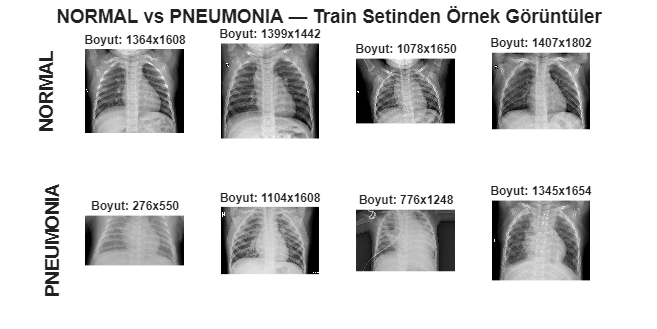

% Train setinden her sınıftan rastgele 4 örnek görüntü göster
figure('Position', [100 100 1200 600], 'Color', 'w');

classes = {'NORMAL', 'PNEUMONIA'};
numSamples = 4;

for c = 1:length(classes)
    folderPath = fullfile(datasetPath, 'train', classes{c});
    files = dir(fullfile(folderPath, '*.jpeg'));
    
    % Rastgele 4 görüntü seç
    rng(42); % tekrar üretilebilirlik için
    randomIdx = randperm(length(files), numSamples);
    
    for s = 1:numSamples
        subplot(2, numSamples, (c-1)*numSamples + s);
        img = imread(fullfile(folderPath, files(randomIdx(s)).name));
        imshow(img);
        
        if s == 1
            ylabel(classes{c}, 'FontSize', 14, 'FontWeight', 'bold');
        end
        
        title(sprintf('Boyut: %dx%d', size(img,1), size(img,2)), 'FontSize', 9);
    end
end

sgtitle('NORMAL vs PNEUMONIA — Train Setinden Örnek Görüntüler', 'FontSize', 14, 'FontWeight', 'bold');

Görüntüler incelendiğinde NORMAL akciğerlerin daha temiz ve net hava boşluklarına sahip olduğu, PNEUMONIA görüntülerinde ise akciğer alanlarında bulanık beyaz lekeler ve yoğunlaşmalar (konsolidasyon) bulunduğu gözlemlenmektedir. Ayrıca görüntülerin farklı boyutlarda olduğu görülmekte; bu nedenle modele vermeden önce hepsini sabit bir boyuta yeniden ölçeklemek gerekecektir.

### 1.4 Sınıf Dağılımının Görselleştirilmesi

Sınıf dağılımını grafik üzerinde göstererek dengesizlik problemini daha net ortaya koyuyoruz. Bu görselleştirme, eğitim sürecinde kullanılacak ağırlıklandırma stratejisinin gerekliliğini somutlaştıracaktır.

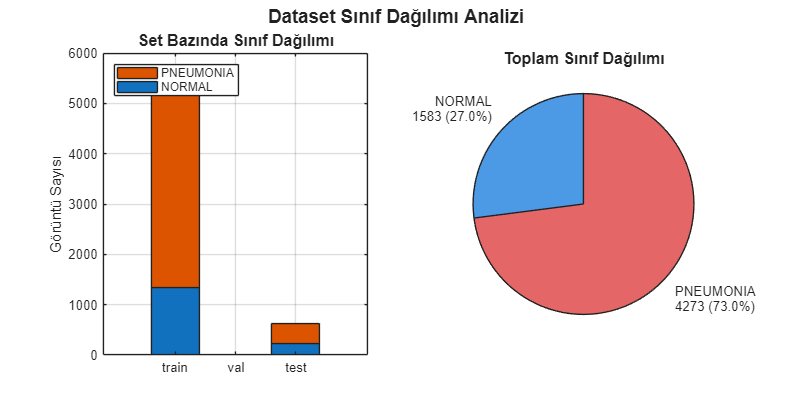

% Sınıf dağılımı bar chart'ı
figure('Position', [100 100 1000 500], 'Color', 'w');

% Train, val, test için stacked bar chart
subplot(1, 2, 1);
bar(counts, 'stacked');
set(gca, 'XTickLabel', sets);
ylabel('Görüntü Sayısı', 'FontSize', 11);
title('Set Bazında Sınıf Dağılımı', 'FontSize', 12, 'FontWeight', 'bold');
legend({'NORMAL', 'PNEUMONIA'}, 'Location', 'northwest');
grid on;

% Toplam dağılım pie chart
subplot(1, 2, 2);
totalCounts = [sum(counts(:,1)), sum(counts(:,2))];
labels = {sprintf('NORMAL\n%d (%.1f%%)', totalCounts(1), 100*totalCounts(1)/sum(totalCounts)), ...
          sprintf('PNEUMONIA\n%d (%.1f%%)', totalCounts(2), 100*totalCounts(2)/sum(totalCounts))};
pie(totalCounts, labels);
title('Toplam Sınıf Dağılımı', 'FontSize', 12, 'FontWeight', 'bold');
colormap([0.3 0.6 0.9; 0.9 0.4 0.4]);

sgtitle('Dataset Sınıf Dağılımı Analizi', 'FontSize', 14, 'FontWeight', 'bold');

Grafiklerden de anlaşılacağı üzere PNEUMONIA sınıfı toplam dataset'in %73'ünü, NORMAL sınıfı ise yalnızca %27'sini oluşturmaktadır. Bu dengesizlik, hiçbir önlem alınmadığında modelin "hep PNEUMONIA tahmin et" gibi kestirme bir strateji geliştirmesine ve görünürde yüksek accuracy elde etmesine rağmen NORMAL örneklerde başarısız olmasına yol açabilir. Bu nedenle eğitim aşamasında sınıf ağırlıklandırma (class weighting) yöntemini uygulayacağız.

## 2. Veri Hazırlığı

### 2.1 imageDatastore ile Veri Yükleme

imageDatastore, MATLAB'ın deep learning iş akışında büyük görüntü koleksiyonlarını verimli şekilde yöneten yapısıdır. Tüm görüntüleri belleğe yüklemek yerine ihtiyaç duyuldukça okur. Klasör isimlerinden otomatik olarak etiket çıkarır, böylece NORMAL ve PNEUMONIA klasörleri sınıf etiketi olarak işlenir.

% Train, validation ve test için ayrı imageDatastore'lar oluştur
imdsTrain = imageDatastore(fullfile(datasetPath, 'train'), ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

imdsVal = imageDatastore(fullfile(datasetPath, 'val'), ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

imdsTest = imageDatastore(fullfile(datasetPath, 'test'), ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Bilgi yazdır
fprintf('imageDatastore Yapıları:\n');

imageDatastore Yapıları:


fprintf('-----------------------------------\n');

-----------------------------------


fprintf('Train  : %d görüntü\n', numel(imdsTrain.Files));

Train  : 5216 görüntü


fprintf('Val    : %d görüntü\n', numel(imdsVal.Files));

Val    : 16 görüntü


fprintf('Test   : %d görüntü\n', numel(imdsTest.Files));

Test   : 624 görüntü


fprintf('-----------------------------------\n');

-----------------------------------



% Sınıf etiketlerini kontrol et
fprintf('\nTrain seti sınıf dağılımı:\n');


Train seti sınıf dağılımı:


disp(countEachLabel(imdsTrain));

      Label      Count
    _________    _____

    NORMAL       1341 
    PNEUMONIA    3875 




fprintf('\nVal seti sınıf dağılımı:\n');


Val seti sınıf dağılımı:


disp(countEachLabel(imdsVal));

      Label      Count
    _________    _____

    NORMAL         8  
    PNEUMONIA      8  




fprintf('\nTest seti sınıf dağılımı:\n');


Test seti sınıf dağılımı:


disp(countEachLabel(imdsTest));

      Label      Count
    _________    _____

    NORMAL        234 
    PNEUMONIA     390 



imageDatastore yapıları başarıyla oluşturuldu. Train setinde 5216, validation setinde 16, test setinde 624 görüntü bulunmaktadır. Validation setinin yalnızca 16 görüntü içermesi modelin doğrulama performansını güvenilir şekilde ölçmek için yetersizdir; bu nedenle bir sonraki adımda train setinden bir kısım ayırarak validation setini genişleteceğiz.

### 2.2 Validation Set'in Yeniden Düzenlenmesi

Orijinal validation seti yalnızca 16 görüntüden oluştuğu için modelin gerçek performansını ölçmek açısından yetersizdir. Bu nedenle train setinden %15'lik bir kısmı validation olarak ayırıyoruz. splitEachLabel fonksiyonu, sınıf oranlarını koruyarak (stratified split) bölme yapar; bu sayede train ve val setlerinde sınıf dağılımı dengesi bozulmaz.

% Mevcut val setini train ile birleştir, sonra yeniden böl
% Önce orijinal val setini yedekle
imdsValOriginal = imdsVal;

% Train setinden %85 train, %15 val olacak şekilde stratified split
[imdsTrain, imdsVal] = splitEachLabel(imdsTrain, 0.85, 'randomized');

% Yeni dağılımı yazdır
fprintf('Yeniden Düzenlenmiş Set Dağılımları:\n');

Yeniden Düzenlenmiş Set Dağılımları:


fprintf('-----------------------------------\n');

-----------------------------------


fprintf('Train  : %d görüntü\n', numel(imdsTrain.Files));

Train  : 4434 görüntü


fprintf('Val    : %d görüntü\n', numel(imdsVal.Files));

Val    : 782 görüntü


fprintf('Test   : %d görüntü (değişmedi)\n', numel(imdsTest.Files));

Test   : 624 görüntü (değişmedi)


fprintf('-----------------------------------\n');

-----------------------------------



fprintf('\nYeni Train sınıf dağılımı:\n');


Yeni Train sınıf dağılımı:


disp(countEachLabel(imdsTrain));

      Label      Count
    _________    _____

    NORMAL       1140 
    PNEUMONIA    3294 




fprintf('\nYeni Val sınıf dağılımı:\n');


Yeni Val sınıf dağılımı:


disp(countEachLabel(imdsVal));

      Label      Count
    _________    _____

    NORMAL        201 
    PNEUMONIA     581 



Validation setimiz artık 782 görüntüye ulaşarak modelin performansını anlamlı şekilde ölçebilecek büyüklüğe geldi. Stratified split sayesinde train ve val setlerindeki NORMAL/PNEUMONIA oranları (%26-%74) birbiriyle tutarlı şekilde korundu. Test seti ise dokunulmadan bırakıldı; bu set modelin daha önce hiç görmediği veriler olarak son değerlendirme aşamasında kullanılacak.

### 2.3 Görüntü Boyutlarının Analizi

Datasetteki görüntülerin farklı boyutlarda olduğunu daha önce gözlemlemiştik. Modele vermeden önce hepsini sabit bir boyuta yeniden ölçeklemek (resize) gerekiyor. Doğru boyut seçimi için önce mevcut boyut dağılımını incelemekte fayda var.

% Train setinden 200 rastgele görüntünün boyutlarını analiz et
rng(42);
sampleSize = 200;
sampleIdx = randperm(numel(imdsTrain.Files), sampleSize);

heights = zeros(sampleSize, 1);
widths = zeros(sampleSize, 1);
channels = zeros(sampleSize, 1);

for i = 1:sampleSize
    info = imfinfo(imdsTrain.Files{sampleIdx(i)});
    heights(i) = info.Height;
    widths(i) = info.Width;
    channels(i) = info.NumberOfSamples;
end

% İstatistikler
fprintf('Görüntü Boyut İstatistikleri (200 örnek üzerinden):\n');

Görüntü Boyut İstatistikleri (200 örnek üzerinden):


fprintf('-----------------------------------\n');

-----------------------------------


fprintf('Yükseklik - Min: %d, Max: %d, Ortalama: %.0f\n', min(heights), max(heights), mean(heights));

Yükseklik - Min: 173, Max: 2578, Ortalama: 1007


fprintf('Genişlik  - Min: %d, Max: %d, Ortalama: %.0f\n', min(widths), max(widths), mean(widths));

Genişlik  - Min: 448, Max: 2633, Ortalama: 1366


fprintf('Kanal sayısı dağılımı: %s\n', mat2str(unique(channels)'));

Kanal sayısı dağılımı: [1 3]


fprintf('-----------------------------------\n');

-----------------------------------


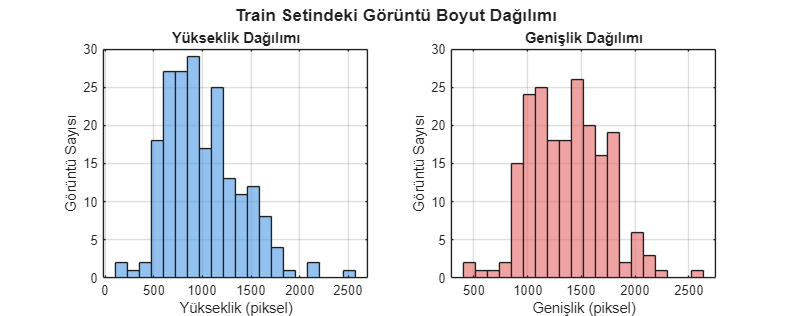


% Histogram olarak görselleştir
figure('Position', [100 100 1000 400], 'Color', 'w');

subplot(1, 2, 1);
histogram(heights, 20, 'FaceColor', [0.3 0.6 0.9]);
xlabel('Yükseklik (piksel)');
ylabel('Görüntü Sayısı');
title('Yükseklik Dağılımı');
grid on;

subplot(1, 2, 2);
histogram(widths, 20, 'FaceColor', [0.9 0.4 0.4]);
xlabel('Genişlik (piksel)');
ylabel('Görüntü Sayısı');
title('Genişlik Dağılımı');
grid on;

sgtitle('Train Setindeki Görüntü Boyut Dağılımı', 'FontSize', 13, 'FontWeight', 'bold');

Görüntülerin yükseklik aralığı 173-2578 piksel, genişlik aralığı ise 448-2633 piksel arasında değişmektedir. Ortalama boyut yaklaşık 1007x1366 piksel olup oldukça büyük bir veridir; bu boyutta modele vermek hesaplama açısından imkansız olacaktır. Ayrıca kanal sayısı dağılımının [1 3] olması, datasette hem gri tonlamalı (1 kanal) hem de RGB (3 kanal) görüntülerin bulunduğunu göstermektedir. Bu nedenle önişleme aşamasında tüm görüntüleri 224x224 boyutuna küçültecek ve kanal sayılarını standart hale getireceğiz.

### 2.4 Önişleme ve Veri Çoğaltma

Modele vermeden önce tüm görüntüleri 224x224 piksel boyutuna küçültüyor ve gri tonlamalı görüntüleri RGB formatına çeviriyoruz. Train setine ek olarak veri çoğaltma (data augmentation) tekniklerini de uyguluyoruz: rastgele döndürme, yatay yansıtma ve kaydırma. Bu işlem train setini sanal olarak büyüterek modelin farklı varyasyonlara karşı dayanıklı olmasını sağlar ve overfitting riskini azaltır. Validation ve test setlerinde augmentation uygulanmaz; sadece resize ve kanal dönüşümü yapılır.

% Hedef giriş boyutu
inputSize = [224 224 3];

% Train için augmentation tanımla
augmenter = imageDataAugmenter( ...
    'RandRotation', [-15 15], ...
    'RandXReflection', true, ...
    'RandXTranslation', [-10 10], ...
    'RandYTranslation', [-10 10]);

% Augmented datastore'lar
augTrain = augmentedImageDatastore(inputSize, imdsTrain, ...
    'DataAugmentation', augmenter, ...
    'ColorPreprocessing', 'gray2rgb');

augVal = augmentedImageDatastore(inputSize, imdsVal, ...
    'ColorPreprocessing', 'gray2rgb');

augTest = augmentedImageDatastore(inputSize, imdsTest, ...
    'ColorPreprocessing', 'gray2rgb');

fprintf('Augmented Datastore''lar Oluşturuldu:\n');

Augmented Datastore'lar Oluşturuldu:


fprintf('-----------------------------------\n');

-----------------------------------


fprintf('Hedef boyut: %dx%dx%d\n', inputSize(1), inputSize(2), inputSize(3));

Hedef boyut: 224x224x3


fprintf('Train: %d görüntü (augmentation aktif)\n', augTrain.NumObservations);

Train: 4434 görüntü (augmentation aktif)


fprintf('Val  : %d görüntü\n', augVal.NumObservations);

Val  : 782 görüntü


fprintf('Test : %d görüntü\n', augTest.NumObservations);

Test : 624 görüntü


fprintf('-----------------------------------\n');

-----------------------------------


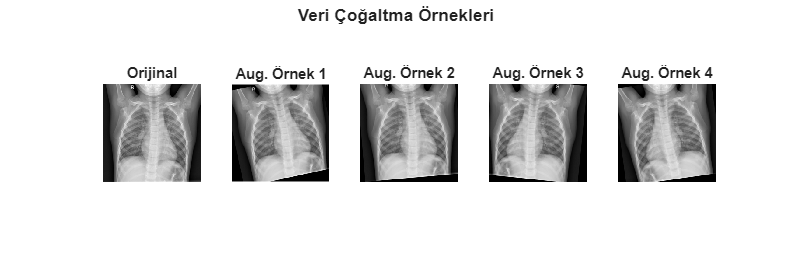


% Augmentation örneklerini göster
figure('Position', [100 100 1200 400], 'Color', 'w');
sampleImg = readimage(imdsTrain, 1);
if size(sampleImg, 3) == 1
    sampleImg = cat(3, sampleImg, sampleImg, sampleImg);
end
sampleImg = imresize(sampleImg, [224 224]);

subplot(1, 5, 1);
imshow(sampleImg);
title('Orijinal', 'FontSize', 11);

for i = 1:4
    augImg = augment(augmenter, sampleImg);
    subplot(1, 5, i+1);
    imshow(augImg);
    title(sprintf('Aug. Örnek %d', i), 'FontSize', 11);
end

sgtitle('Veri Çoğaltma Örnekleri', 'FontSize', 13, 'FontWeight', 'bold');

Augmented datastore'lar başarıyla oluşturuldu. Train setine uygulanan veri çoğaltma örnekleri yukarıda görülmektedir; orijinal görüntü ile dört farklı varyasyon karşılaştırıldığında modelin aynı akciğeri farklı açı, yön ve konumlarda görerek öğreneceği anlaşılmaktadır. Bu işlem, modelin gerçek dünyada karşılaşacağı varyasyonlara karşı genelleme yeteneğini artırır ve overfitting riskini azaltır. Validation ve test setlerinde augmentation uygulanmaması, modelin gerçek performansının objektif şekilde ölçülebilmesi için kritiktir.

## 3. CNN Modelinin Tasarımı

Sıfırdan kendi CNN modelimizi tasarlıyoruz. Mimari, dört evrişim bloğundan ve sonrasında tam bağlantılı katmanlardan oluşmaktadır. 

Her evrişim bloğu sırasıyla Convolution, Batch Normalization, ReLU ve Max Pooling katmanlarını içerir. Filtre sayısı her blokta iki katına çıkarılarak (32 → 64 → 128 → 128) hiyerarşik özellik öğrenmesi sağlanır: ilk katmanlar kenar ve doku gibi düşük seviyeli özellikleri, sonraki katmanlar ise daha karmaşık desenleri yakalar. Son katmanda Dropout ile overfitting önlenmeye çalışılır ve iki sınıflı çıkış için Softmax kullanılır.

% CNN Mimarisi
layers = [
    % Giriş katmanı
    imageInputLayer(inputSize, 'Name', 'input', 'Normalization', 'zerocenter')
    
    % Block 1: 32 filter
    convolution2dLayer(3, 32, 'Padding', 'same', 'Name', 'conv1')
    batchNormalizationLayer('Name', 'bn1')
    reluLayer('Name', 'relu1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool1')
    
    % Block 2: 64 filter
    convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'conv2')
    batchNormalizationLayer('Name', 'bn2')
    reluLayer('Name', 'relu2')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool2')
    
    % Block 3: 128 filter
    convolution2dLayer(3, 128, 'Padding', 'same', 'Name', 'conv3')
    batchNormalizationLayer('Name', 'bn3')
    reluLayer('Name', 'relu3')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool3')
    
    % Block 4: 128 filter
    convolution2dLayer(3, 128, 'Padding', 'same', 'Name', 'conv4')
    batchNormalizationLayer('Name', 'bn4')
    reluLayer('Name', 'relu4')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool4')
    
    % Fully connected katmanlar
    fullyConnectedLayer(256, 'Name', 'fc1')
    reluLayer('Name', 'relu_fc1')
    dropoutLayer(0.5, 'Name', 'dropout')
    
    % Çıkış katmanı (2 sınıf: NORMAL, PNEUMONIA)
    fullyConnectedLayer(2, 'Name', 'fc_out')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'output')
];

% Layer graph oluştur ve görselleştir
lgraph = layerGraph(layers);

% Mimariyi yazdır
fprintf('CNN Mimarisi Özeti:\n');

CNN Mimarisi Özeti:


fprintf('-----------------------------------\n');

-----------------------------------


analyzeNetwork(lgraph);

CNN modeli başarıyla tasarlandı.

Toplam 6.6 milyon öğrenilebilir parametreden oluşan 23 katmanlı bir mimari elde ettik.

 Giriş katmanından başlayarak her evrişim bloğunda görüntü boyutu yarıya inerken (224 → 112 → 56 → 28 → 14) filtre sayısı artarak (32 → 64 → 128 → 128) hiyerarşik özellik çıkarımı sağlanıyor. Son fully connected katmanlardan geçen veri 256 boyutlu özellik vektörüne indirgenerek 2 sınıf (NORMAL/PNEUMONIA) için Softmax ile olasılık dağılımına dönüştürülüyor.

### 3.2 Eğitim Parametreleri ve Sınıf Ağırlıklandırma

Modelin eğitim sürecini yöneten parametreleri tanımlıyoruz. 

Optimizer olarak Adam algoritması seçildi; uyarlanabilir öğrenme oranı sayesinde yakınsama hızlıdır. Mini-batch boyutu 32, başlangıç öğrenme oranı 1e-4 olarak ayarlandı. Sınıf dengesizliğini telafi etmek için her sınıfa ters frekansla orantılı ağırlık veriyoruz; böylece model azınlık sınıfı olan NORMAL örneklerini de gözardı etmeden öğrenir.

% Sınıf ağırlıklarını hesapla (ters frekans yöntemi)
classNames = categories(imdsTrain.Labels);
classCounts = countcats(imdsTrain.Labels);
classWeights = sum(classCounts) ./ (length(classNames) * classCounts);

fprintf('Sınıf Ağırlıkları:\n');

Sınıf Ağırlıkları:


fprintf('-----------------------------------\n');

-----------------------------------


for i = 1:length(classNames)
    fprintf('%-12s: %.4f (örnek sayısı: %d)\n', classNames{i}, classWeights(i), classCounts(i));
end

NORMAL      : 1.9447 (örnek sayısı: 1140)
PNEUMONIA   : 0.6730 (örnek sayısı: 3294)


fprintf('-----------------------------------\n');

-----------------------------------



% Çıkış katmanını ağırlıklı versiyonla değiştir
weightedClassificationLayer = classificationLayer( ...
    'Name', 'output', ...
    'Classes', classNames, ...
    'ClassWeights', classWeights);

lgraph = replaceLayer(lgraph, 'output', weightedClassificationLayer);

% Eğitim parametreleri
options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-4, ...
    'MaxEpochs', 8, ...
    'MiniBatchSize', 32, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augVal, ...
    'ValidationFrequency', 50, ...
    'ValidationPatience', 5, ...
    'Verbose', false, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'auto');

fprintf('\nEğitim Parametreleri:\n');


Eğitim Parametreleri:


fprintf('-----------------------------------\n');

-----------------------------------


fprintf('Optimizer            : Adam\n');

Optimizer            : Adam


fprintf('Başlangıç LR         : 1e-4\n');

Başlangıç LR         : 1e-4


fprintf('Max Epoch            : 8\n');

Max Epoch            : 8


fprintf('Batch Size           : 32\n');

Batch Size           : 32


fprintf('Validation Frequency : her 50 iterasyon\n');

Validation Frequency : her 50 iterasyon


fprintf('Early Stopping       : 5 epoch sabırla\n');

Early Stopping       : 5 epoch sabırla


fprintf('-----------------------------------\n');

-----------------------------------


fprintf('\nEğitim parametreleri hazır. Sonraki hücrede eğitime başlayacağız.\n');


Eğitim parametreleri hazır. Sonraki hücrede eğitime başlayacağız.


Sınıf ağırlıklarını ters frekans yöntemiyle hesapladık. NORMAL sınıfının ağırlığı 1.94 iken PNEUMONIA'nın ağırlığı 0.67 olarak belirlendi; yani modele NORMAL örneklerin yanlış sınıflandırılmasının PNEUMONIA örneklerine kıyasla yaklaşık 2.9 kat daha fazla ceza getireceği bildirildi.

Adam optimizer ve 1e-4 öğrenme oranı seçimleri tıbbi görüntü sınıflandırma çalışmalarında yaygın olarak kullanılan ve hızlı yakınsama sağlayan bir kombinasyondur. ValidationPatience parametresi sayesinde model artık iyileşmiyorsa eğitim erken durdurulur, bu da gereksiz hesaplamayı engeller.

gpuDeviceCount % gpu kontrolü 

ans = 1

### 3.3 Modelin Eğitilmesi

Tanımladığımız mimariyi ve eğitim parametrelerini kullanarak modeli eğitiyoruz.

Eğitim sırasında MATLAB otomatik olarak bir grafik penceresi açacak; bu pencerede train ve validation accuracy/loss değerlerinin epoch'lara göre nasıl değiştiğini canlı olarak gözlemleyebileceğiz. Eğitilmiş model daha sonra tekrar tekrar yüklenebilmesi için diske kaydedilecek.

% Eğitim başlangıç zamanı
fprintf('Eğitim başlıyor...\n');

Eğitim başlıyor...


fprintf('GPU kullanılıyor.\n');

GPU kullanılıyor.


fprintf('-----------------------------------\n');

-----------------------------------


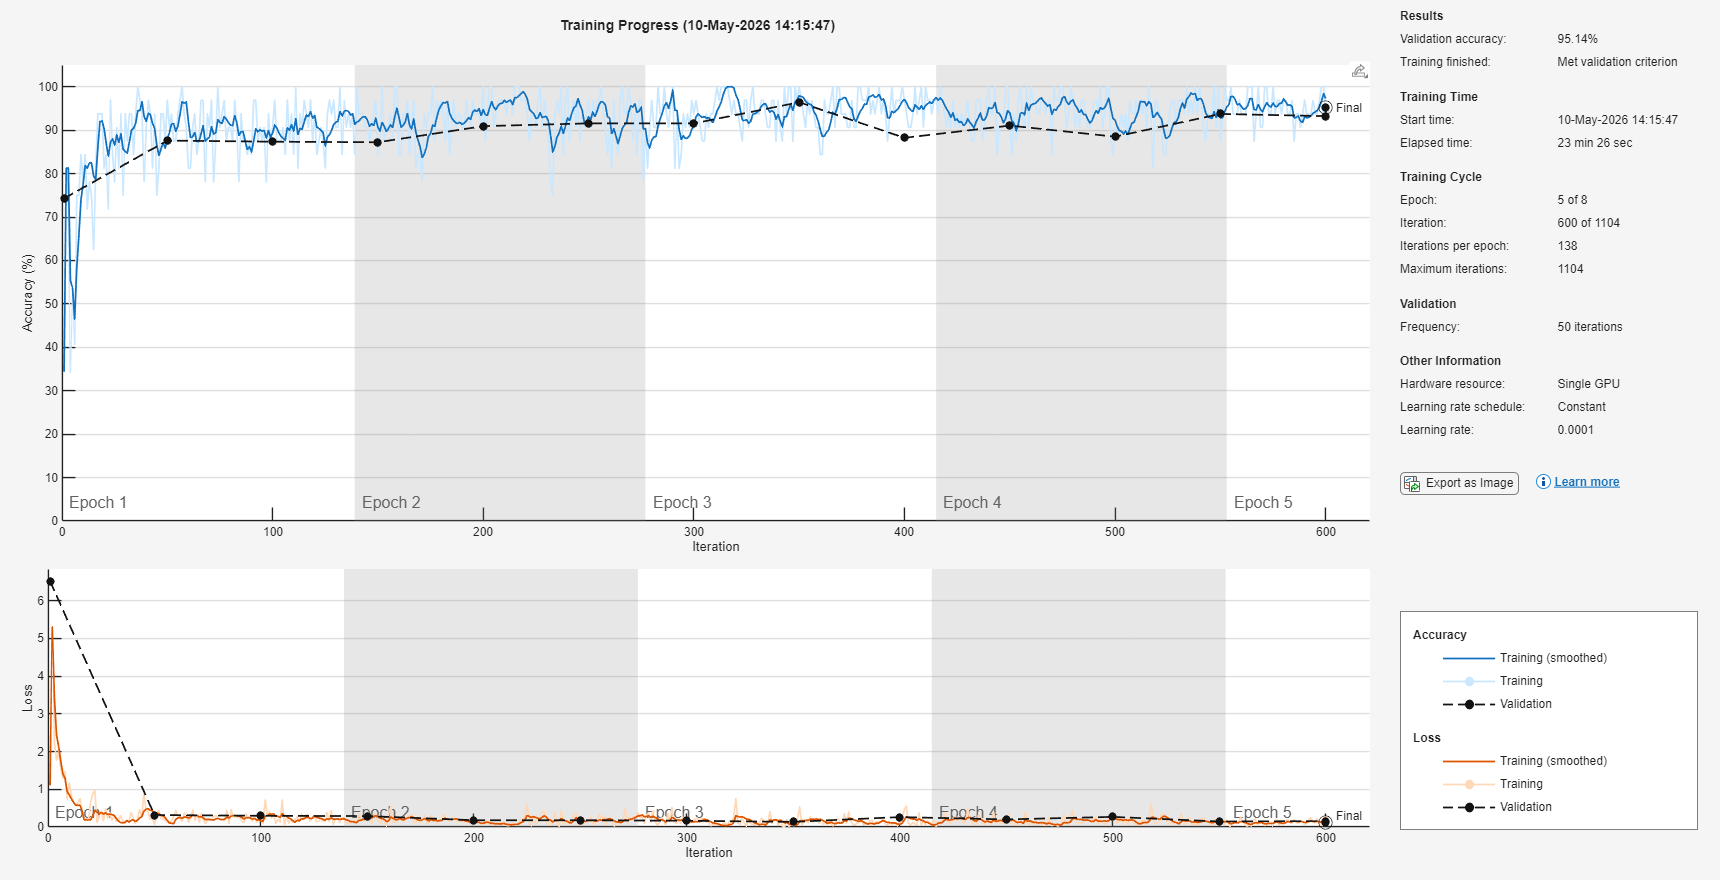


tic;

% Modeli eğit
trainedNet = trainNetwork(augTrain, lgraph, options);


% Eğitim süresi
trainingTime = toc;
fprintf('-----------------------------------\n');

-----------------------------------


fprintf('Eğitim tamamlandı!\n');

Eğitim tamamlandı!


fprintf('Toplam süre: %.2f dakika (%.0f saniye)\n', trainingTime/60, trainingTime);

Toplam süre: 27.81 dakika (1669 saniye)



% Modeli kaydet
modelPath = fullfile(pwd, 'trained_model.mat');
save(modelPath, 'trainedNet', 'classNames', 'inputSize');
fprintf('Model kaydedildi: %s\n', modelPath);

Model kaydedildi: C:\Users\ferit\OneDrive\Belgeler\MATLAB\image-data-presentation\trained_model.mat


Model 5 epoch sonunda erken durdurma (early stopping) kriteri ile eğitimini tamamladı ve %95.14 validation accuracy değerine ulaştı.

Eğitim eğrisi incelendiğinde train ve validation accuracy değerlerinin birbirine yakın seyretmesi, modelin overfit etmediğini ve genelleme yeteneğinin iyi olduğunu göstermektedir. 

Loss değerleri hızla düşerek 0.1 civarında stabilize olmuş; bu da modelin etkili bir şekilde öğrendiğine işaret eder. 

Eğitilmiş model trained_model.mat olarak diske kaydedildi; bu sayede sonraki kullanımlarda yeniden eğitim gerekmeden tahmin yapılabilecek.